# Educator Practice Walkthrough

[⇦  Main Menu](matlab:open('../../MainMenu.mlx')) | [Educator Showcase](matlab:open('./TeachingModuleShowcaseRegressionBasics.mlx'))

Use this walkthrough when an educator asks what students would actually do after the teaching-side demos. It stitches together representative solved sections from [Practice Linear](matlab:open('./Scripts/TryRegression.mlx')), [Practice Polynomial](matlab:open('./Scripts/TryCurvilinearPolynomial.mlx')), [Practice Linearizable Nonlinear](matlab:open('./Scripts/TryCurvilinear.mlx')) and [Practice Multiple](matlab:open('./Scripts/TryMultiple.mlx')) so educators can preview the student coding path.

Use the code-visible, output-inline format during the conversation so the educator can see how the practice files scaffold loading data, fitting models, checking assumptions, and making predictions.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline** using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

 For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections, and they will generate errors if run out of order.

The   and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

To run the code, you can click the 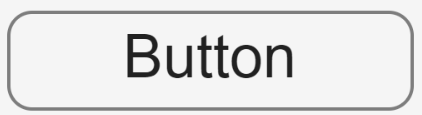 **Button** provided, or you can use [image: Run Section icon] **Run Section** or [image: Run and Advance icon] **Run and Advance** in the Live Editor tab of the tool strip, or the equivalent keyboard commands of Ctrl-Enter to run a section or Ctrl-Shift-Enter to run and advance.

## Notes About this Walkthrough 

This walkthrough uses [Name-Value Arguments](https://www.mathworks.com/help/matlab/matlab_prog/validate-name-value-arguments.html) where MATLAB supports them, such as `DisplayName="Observed data"` and `Location="best"`, so the code style matches the current practice-script conventions.

## Try Linear Regression

[Practice Linear](matlab:open('./Scripts/TryRegression.mlx')) guides students through the complete linear regression workflow in MATLAB: loading data into tables, fitting and visualizing regression models, interpreting coefficients, and using models to make predictions, culminating in a medical ventilator application where they build and apply a regression model to real-world data.

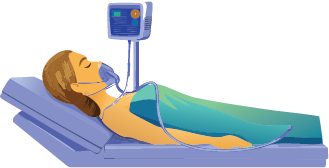

### Load Data into a Table

  **Try.** Run the code below to load the ventilator practice data into a table.

We load the solved ventilator data into a table using MATLAB's built-in functions [`load`](https://www.mathworks.com/help/matlab/ref/load.html) and [`table`](https://www.mathworks.com/help/matlab/ref/table.html).

load(practiceDataFile("Ventilator.mat"),"t","V")
TblVent = table(t(:),V(:),VariableNames=["t","V"]);
head(TblVent)

### Fit the Linear Regression Model

  **Try.** Run the code below to fit the least-squares line and show the two model coefficients.

We fit the least-squares line using MATLAB's built-in function [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html).

mdlVent = fitlm(TblVent,"V ~ t");
disp("Model Coefficients:")
disp("Slope (b1): " + mdlVent.Coefficients.Estimate(2))
disp("Intercept (b0): " + mdlVent.Coefficients.Estimate(1))

### Plot the Linear Fit

  **Try.** Run the code below to show the fitted line before talking through the prediction step.

We draw the fitted line using MATLAB's built-in functions [`predict`](https://www.mathworks.com/help/search.html?qdoc=predict) and [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html).

tGrid = linspace(min(TblVent.t),max(TblVent.t),200)';
VFitGrid = predict(mdlVent,table(tGrid,VariableNames="t"));

figure
plot(mdlVent)

### Predict at `t = 7.5` and Mark the Response

  **Try.** Run the code below to show the prediction step that students repeat in `TryRegression.mlx`.

We predict the response at `t = 7.5` using MATLAB's built-in function [`predict`](https://www.mathworks.com/help/search.html?qdoc=predict).

tTarget = 7.5;
VTarget = predict(mdlVent,table(tTarget,VariableNames="t"));
hold on
scatter(tTarget,VTarget,60,"d","filled",DisplayName="Predicted point")
legend("show",Location="best")
hold off
disp(table(tTarget,VTarget,VariableNames=["t","PredictedV"]))

## Try Curvilinear: Polynomial

[Practice Polynomial](matlab:open('./Scripts/TryCurvilinearPolynomial.mlx')) guides students through fitting, visualizing, and using polynomial regression models in MATLAB. Through synthetic polynomial data, centrifugal pump performance, and bioreactor applications, students learn how to identify polynomial relationships, fit best‑fit curves with `polyfit` and `polyval`, visualize model predictions, and use polynomial models to predict responses from new inputs.

[image: Bioreactor cartoon]

**Bioreactor**

### Choose a Polynomial Practice Scenario

  **Try.** Choose a value from the **Polynomial scenario** dropdown and click the **Plot Polynomial Practice Fit** button to show one representative student workflow.

We fit and evaluate the quadratic model using MATLAB's built-in functions [`polyfit`](https://www.mathworks.com/help/matlab/ref/polyfit.html) and [`polyval`](https://www.mathworks.com/help/matlab/ref/polyval.html).

PolynomialScenario ="Bioreactor temperature";
 
switch PolynomialScenario
    case "Bioreactor temperature"
        load(practiceDataFile("Bioreactor.mat"),"Temp","Prod")
        TblPoly = sortrows(table(Temp(:),Prod(:),VariableNames=["x","y"]),"x");
        xLabel = "Bioreactor temperature (degC)";
        yLabel = "Product titer";
        plotTitle = "Bioreactor Polynomial Practice Checkpoint";
        targetX = 36.8;
        targetLabel = "Prediction at 36.8 degC";
    otherwise
        rng(7,"twister")
        Q = (0:0.005:0.06)';
        HTrue = 45 - 450 * Q - 5000 * Q.^2;
        HExp = cummin(HTrue + randn(size(HTrue)));
        TblPoly = table(Q,HExp,VariableNames=["x","y"]);
        xLabel = "Flow rate (m^3/s)";
        yLabel = "Pump head (m)";
        plotTitle = "Centrifugal Pump Polynomial Practice Checkpoint";
        targetX = 0.032;
        targetLabel = "Prediction at 0.032 m^3/s";
end

polyCoeffs = polyfit(TblPoly.x,TblPoly.y,2);
xGrid = linspace(min(TblPoly.x),max(TblPoly.x),200)';
yFit = polyval(polyCoeffs,xGrid);
yTarget = polyval(polyCoeffs,targetX);

figure
scatter(TblPoly.x,TblPoly.y,24,"filled",DisplayName="Observed data")
hold on
plot(xGrid,yFit,LineWidth=1.8,DisplayName="Quadratic fit")
scatter(targetX,yTarget,60,"d","filled",DisplayName=targetLabel)
hold off
legend("show",Location="best")
xlabel(xLabel)
ylabel(yLabel)
title(plotTitle)
grid on
box on

disp(table(targetX,yTarget,VariableNames=["TargetInput","PredictedResponse"]))

## Try Curvilinear: Linearizable

[Practice Linearizable Nonlinear](matlab:open('./Scripts/TryCurvilinear.mlx')) guides students through identifying, linearizing, and modeling nonlinear relationships using linear regression techniques in MATLAB. Through power-law, battery degradation, and motor thermal saturation applications, students learn to select appropriate linearization strategies, fit regression models to transformed data, make predictions, and convert results back to their original nonlinear form for interpretation.

[image: Illustration of a rechargable battery]

### Choose a Linearizable Scenario

  **Try.** Choose a value from the **Linearizable scenario** dropdown and click the **Plot Linearizable Practice Fit** button to compare the transformed and recovered views.

We fit the transformed line using MATLAB's built-in function [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) and recover predictions with MATLAB's built-in function [`predict`](https://www.mathworks.com/help/search.html?qdoc=predict).

LinearizableScenario = "Battery lifetime decay";
 
switch LinearizableScenario
    case "Battery lifetime decay"
        load(practiceDataFile("BatterySOH.mat"),"t","SOH")
        valid = SOH > 0;
        xRaw = t(valid);
        yRaw = SOH(valid);
        xTransform = xRaw;
        yTransform = log(yRaw);
        targetX = 5.3;
        rawTitle = "Battery Lifetime Practice Checkpoint";
        transformTitle = "Battery Transform Check";
        rawXLabel = "Time";
        rawYLabel = "State of health";
        transformXLabel = "Time";
        transformYLabel = "log(SOH)";
        rawFitFcn = @(mdl,xValues) exp(predict(mdl,xValues));
        targetTransformX = targetX;
        targetName = "Predicted SOH";
    otherwise
        rng(11,"twister")
        time = linspace(0.5,10,100)';
        Temp = 5 * (time ./ (2 + time)) + 0.05 * randn(size(time));
        valid = Temp > 0;
        xRaw = time(valid);
        yRaw = Temp(valid);
        xTransform = 1 ./ xRaw;
        yTransform = 1 ./ yRaw;
        targetX = 5;
        rawTitle = "Motor Saturation Practice Checkpoint";
        transformTitle = "Motor Reciprocal Transform Check";
        rawXLabel = "Time";
        rawYLabel = "Temperature";
        transformXLabel = "1 / time";
        transformYLabel = "1 / temperature";
        rawFitFcn = @(mdl,xValues) 1 ./ predict(mdl,1 ./ xValues);
        targetTransformX = 1 ./ targetX;
        targetName = "Predicted temperature";
end

mdlTransform = fitlm(xTransform,yTransform);
xTransformGrid = linspace(min(xTransform),max(xTransform),200)';
yTransformFit = predict(mdlTransform,xTransformGrid);

xRawGrid = linspace(min(xRaw),max(xRaw),200)';
yRawFit = rawFitFcn(mdlTransform,xRawGrid);
targetRawY = rawFitFcn(mdlTransform,targetX);
targetTransformY = predict(mdlTransform,targetTransformX);

figure
tiledlayout(1,2,Padding="compact",TileSpacing="compact")

nexttile
scatter(xRaw,yRaw,24,"filled",DisplayName="Observed data")
hold on
plot(xRawGrid,yRawFit,LineWidth=1.8,DisplayName="Recovered fit")
scatter(targetX,targetRawY,60,"d","filled",DisplayName=targetName)
hold off
legend("show",Location="best")
xlabel(rawXLabel)
ylabel(rawYLabel)
title(rawTitle)
grid on
box on

nexttile
scatter(xTransform,yTransform,24,"filled",DisplayName="Transformed data")
hold on
plot(xTransformGrid,yTransformFit,LineWidth=1.8,DisplayName="Linear fit")
scatter(targetTransformX,targetTransformY,60,"d","filled", ...
    DisplayName="Transformed prediction")
hold off
legend("show",Location="best")
xlabel(transformXLabel)
ylabel(transformYLabel)
title(transformTitle)
grid on
box on

disp(table(targetX,targetRawY,VariableNames=["TargetInput","PredictedResponse"]))

## Try Multiple Regression

[Practice Multiple](matlab:open('./Scripts/TryMultiple.mlx')) guides students through the complete multiple regression workflow in MATLAB, including fitting models, interpreting ANOVA results, and evaluating the assumptions of linearity, independence, equal variance, and normality using diagnostic plots. Through synthetic datasets and a DC power consumption application, students build, assess, and validate multiple regression models while gaining hands-on experience with model interpretation and prediction.

### Load Data and Fit the Full Model

  **Try.** Run the code below to load the DC power practice data, organize it into a table, and fit the full model once.

We load the DC power practice variables into a table using MATLAB's built-in functions [`load`](https://www.mathworks.com/help/matlab/ref/load.html) and [`table`](https://www.mathworks.com/help/matlab/ref/table.html) and fit the full model using MATLAB's built-in function [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html).

load(practiceDataFile("DCPowerData.mat"),"TrafficLoad","ActiveModules","AmbientTemp","DCPower")
TblPower = table(TrafficLoad,ActiveModules,AmbientTemp,DCPower, ...
    VariableNames=["TrafficLoad","ActiveModules","AmbientTemp","DCPower"]);

mdlPower = fitlm(TblPower,"DCPower ~ TrafficLoad + ActiveModules + AmbientTemp");
anova(mdlPower,"summary")

### Choose a Predictor to Screen for Linearity

  **Try.** Choose a value from the **Linearity plot** dropdown and click the **Show Selected Linearity Screen** button to preview the first student-facing screen.

We screen one predictor at a time using MATLAB's built-in functions [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) and [`predict`](https://www.mathworks.com/help/search.html?qdoc=predict).

Choose a predictor, run the section, and use the plot as the first conversation about whether a multiple linear model is reasonable.

LinearityPlot = "Traffic load";
 
switch LinearityPlot
    case "Traffic load"
        predictorData = TblPower.TrafficLoad;
        predictorLabel = "Traffic load";
    case "Active modules"
        predictorData = TblPower.ActiveModules;
        predictorLabel = "Active modules";
    otherwise
        predictorData = TblPower.AmbientTemp;
        predictorLabel = "Ambient temperature (degC)";
end

TblLinearity = table(predictorData,TblPower.DCPower,VariableNames=["x","DCPower"]);
mdlScreen = fitlm(TblLinearity,"DCPower ~ x");
xGrid = linspace(min(TblLinearity.x),max(TblLinearity.x),200)';
yFit = predict(mdlScreen,table(xGrid,VariableNames="x"));

figure
scatter(TblLinearity.x,TblLinearity.DCPower,24,"filled",DisplayName="Observed data")
hold on
plot(xGrid,yFit,LineWidth=1.8,DisplayName="Linear screen")
hold off
xlabel(predictorLabel)
ylabel("DC power (W)")
title("Linearity Screen: " + predictorLabel)
legend("show",Location="best")
grid on
box on

disp(table(string(LinearityPlot),mdlScreen.Rsquared.Ordinary,VariableNames=["PredictorScreen","Rsquared"]))

### Assumptions and Conditions of Linearity

### Check Linearity Assumption

  **Try.** Run the code below to show the residuals-versus-fitted view that students use after the predictor screen.

We inspect the fitted-value residual view using MATLAB's built-in function [`plotResiduals`](https://www.mathworks.com/help/search.html?qdoc=plotResiduals).

figure
tiledlayout(1,3)
nexttile
plotResiduals(mdlPower,"fitted")
xlabel("Fitted value")
ylabel("Residual")
title("Linearity")

sgtitle("Check Assumptions:")

### Check Independence Assumption

  **Try.** Run the code below to show the case-order residual view that students use when they discuss independence.

We inspect the case-order residual view using MATLAB's built-in function [`plotResiduals`](https://www.mathworks.com/help/search.html?qdoc=plotResiduals).

nexttile
plotResiduals(mdlPower,"caseorder")
xlabel("Observation order")
ylabel("Residual")
title("Indepedence")

### Check Equal Variance Assumption

  **Try.** Run the code below to show the residuals-versus-fitted view that students use after the predictor screen.

We inspect the case-order residual view using MATLAB's built-in function [`plotResiduals`](https://www.mathworks.com/help/search.html?qdoc=plotResiduals).

nexttile
plotResiduals(mdlPower,"fitted")
xlabel("Fitted value")
ylabel("Residual")
title("Equal Variance")

### Check Normality

  **Try.** Run the code below to show the histogram and probability views that students use when they check normality.

We inspect the histogram and probability views using MATLAB's built-in function [`plotResiduals`](https://www.mathworks.com/help/search.html?qdoc=plotResiduals).

figure
sgtitle("Check Normality Assumption")
tiledlayout(1,2)
nexttile
plotResiduals(mdlPower,"histogram")
title("Residual Histogram")

nexttile
plotResiduals(mdlPower,"probability")
title("Residual Probability Plot")

## Wrap-Up

Use one checkpoint when the educator asks, "What would my students type next?" Start with the linear sequence for a short answer, use the DC power residual checks when the course emphasizes assumptions, and choose one curvilinear checkpoint when the educator wants model-form choice beyond a straight line.

Pair this walkthrough with [TeachingModuleShowcaseRegressionBasics.mlx](matlab:open('./TeachingModuleShowcaseRegressionBasics.mlx')) when you want to move back to the teaching-side story.

[⇦ Return to the Main Menu](matlab:open('../../MainMenu.mlx'))

## Local Helper Functions

function dataFile = practiceDataFile(filename)
showcaseRoot = getPracticeWalkthroughRoot;
dataFile = fullfile(showcaseRoot,"Data",filename);
end

function showcaseRoot = getPracticeWalkthroughRoot
candidateRoots = strings(0,1);

if usejava("desktop")
    activeFile = string(matlab.desktop.editor.getActiveFilename);
    if strlength(activeFile) > 0
        candidateRoots(end+1,1) = string(fileparts(activeFile));
    end
end

scriptPath = string(mfilename("fullpath"));
if strlength(scriptPath) > 0
    candidateRoots(end+1,1) = string(fileparts(scriptPath));
end

candidateRoots(end+1,1) = string(pwd);
candidateRoots = unique(candidateRoots,"stable");

for idx = 1:numel(candidateRoots)
    candidateRoot = candidateRoots(idx);
    if isfolder(fullfile(candidateRoot,"Data"))
        showcaseRoot = candidateRoot;
        return
    end
end

showcaseRoot = string(pwd);
end